# Laboratorio 1: Beardo - Caviglia - Di Via

## Background Teorico 

AIA (Atmospheric Imaging Assembly) è un quadritelescopio facente parte del SDO(Solar Dynamics Observatory), una missione lanciata nel 2010 per comprendere le cause delle attività del sole e i loro impatti sulla terra. AIA osserva all'interno dello spettro ultravioletto e restituisce ogni 12 secondi sette immagini da 4096 x 4096 pixel raffiguranti la corona (parte più esterna) del sole.

### **Fenomeno della Saturazione e Blooming**

Nelle osservazioni solari, un problema comune è la **saturazione** dell'immagine, che si verifica quando l'intensità della luce supera la soglia massima gestibile dai sensori CCD (Charge-Coupled Device), dispositivi che contano i fotoni ma possono registrare un valore massimo di 16383 DN (Digital Number) per pixel. Quando il conteggio di fotoni in un pixel raggiunge questo limite, il pixel appare "saturo" (bianco), e l'informazione originale viene persa. Inoltre, nei CCD si manifesta un rumore poissoniano, dovuto alla natura discreta del conteggio dei fotoni.

In termini pratici, la regione di** saturazione S** viene definita come l'unione di una regione di** saturazione primaria S'** e di una regione di **blooming B:** 

$S:=\left\lbrace \left(x,y\right)\in X\times Y|\;h\left(x,y\right)\ge M\right\rbrace =S^{\prime } \cup B$,

dove $h(x,y)$ è il segnale acquisito in corrispondenza del pixel $(x,y)$ e $M$ è la soglia massima di 16383 DN/pixel.

Il blooming è l'effetto per cui la carica in eccesso nei pixel saturi "straripa" nei pixel adiacenti, formando un alone verticale che altera ulteriormente l’immagine. Di fatto, questo rende indistinguibile a priori la zona di blooming dalla saturazione primaria, complicando l’elaborazione dei dati.

### **PSF e Frange associate alla Regione di Saturazione**

La **PSF** (Point Spread Function) di AIA indicata con $K$ modellizza la distorsione di un punto luminoso a causa delle caratteristiche ottiche e fisiche del sistema (come **diffrazione** e **diffusione)**, che alterano la propagazione della luce e, di conseguenza, la qualità dell’immagine acquisita. Si definisce quindi come somma di una componente di diffrazione $K_d$ e una di diffusione (o di core) $K_c$.

La componente di diffrazione della PSF crea** frange** luminose intorno a punti intensi per via della dispersione della luce attraverso le ottiche, mentre la componente di diffusione provoca una sfocatura più ampia a causa di imperfezioni nei materiali, contribuendo maggiormente al fenomeno di blooming.

Le frange contengono informazioni preziose che possono essere utilizzate per stimare la luminosità originaria della zona satura, contribuendo così al processo di desaturazione, e sono definite come segue:


$$F=\{ (x,y) \in \mathit{X} \times \mathit{Y}  \backslash S \quad t.c. \quad(K_D * 1_S)(x,y) \not =0\}$$


$F'=\{ (x,y) \in \mathit{X} \times \mathit{Y}  \backslash S \quad t.c. \quad  (K_D * 1_{S'})(x,y) \not =0\}$, 

dove $1_S$ e $1_{S'}$  sono le funzioni caratteristiche su $S$ e $S'$ rispettivamente.

Grazie all'ipotesi per cui nelle frange gli effetti di diffrazione associati al blooming sono trascurabili, si arriva alla formulazione

$h=K * f=K_D*f+K_C*f=K_D*f_{|S'}+K_D*f_{|\overline{S'}}+K_C*f=K_D*f_{|S'}+K_C*f$,

dove $h$ è l'immagine ottenuta dal processo di formazione del segnale. Denotando con $g$ l'immagine saturata $$ g(x,y) =\begin{cases} h(x,y)  \qquad se \quad (x,y) \in  \overline{S}\\
M \qquad \quad se \quad (x,y) \in  S \end{cases}$ si ottiene che


$$(1) \qquad \qquad g_{|F'}=h_{|F'}=(K_D*f_{|S'})_{|F'}+(K_C*f)_{|F'}$$


dove si definisce il background $BG=(K_C*f)$.

### **Problema del Background**

Per risolvere il problema della saturazione e ottenere una ricostruzione accurata dell'immagine, è necessario stimare il background dell’immagine (BG). 

In alcuni casi, il background può essere stimato utilizzando immagini **pre** e **post** saturazione. Questo è possibile grazie alla funzione di chiusura dei CCD: quando il conteggio di fotoni supera il limite di saturazione, i CCD diminuiscono automaticamente il tempo di esposizione, evitando la saturazione e fornendo un’immagine non saturata. 

### Continuo - discreto

Definita una griglia di punti equispaziati $\{ (x_p, y_q)\}_{p,q=1,...,n}$ con $n=4096$, avremo che l'immagine $I$ è data da $g$ campionata nei punti della nostra griglia, e sarà una matrice $n \times n$ (oppure un vettore  $n^2 \times 1$). Con abuso di notazione si definiscono $S$ e $F$ discreti in modo del tutto analogo al caso continuo, mentre $K$ diventa una matrice circolante $K= \{ K(x_p -x_{p'}, y_q-y_{q'}) \}_{p,p',q,q'=1,.....,n}$; se si fissa la coppia $(x_{p'}, y_{q'})$, si può vedere come una discretizzazione di $K$ centrata in $(x_{p'}, y_{q'})$ (questa osservazione verrà utilizzata successivamente per la costruzione della matrice). 

L'equazione $(1)$  nel discreto, equivale all'equazione 

$I_{F'}=K_D^{S'}\cdot x_{S'}^* + BG_{F'}$,

dove $x^*_{S'}=\{ f(x_p,y_q)\}_{p,q=1,....,n}$ e dove $K_D^{S'}$ è un operatore lineare che va da $S'$ in $F'$.  Con un abuso di notazione si indicano sempre con $I_{F'}$l'immagine ridotta a $F'$ discretizzata e con $BG_{|F'}$ il background ridotto ad $F'$ discretizzato. 

## Introduzione al Laboratorio

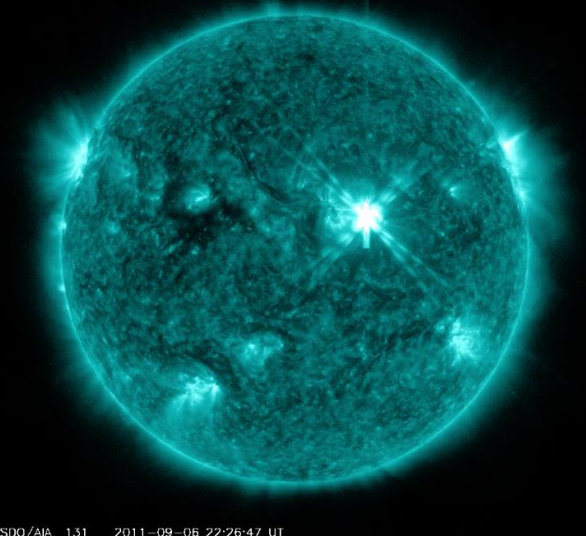

L'obiettivo di questo laboratorio è ricostruire la zona saturata dell'immagine catturata da AIA il 6 settembre 2011 - UT 22:26:47, in quanto in tale zona è dove si è verificato il brillamento solare ed è quindi quella di maggiore interesse.

Per recuperare le informazioni, bisogna risolvere il problema di saturazione, ovvero ricavare il flusso ristretto alla zona di saturazione primaria $x_{S'}^*$ dall'equazione

$I_{F'}=K_D^{S'}\cdot x_{S'}^* + BG_{F'}$.

Supponendo di conoscere $S'$ e, siccome $BG$ è noto (e in particolare$BG_{F'}$ ), si può risolvere il problema inverso  $y=Ax+b$ tramite una formulazione bayesiana del problema, che conduce ad un'equazione di punto fisso risolvibile attraverso il metodo iterativo Expectation Maximization (EM):

$x^{(k+1)}=x^{(k)} \cdot A^T \left(\frac{y}{Ax^{(k)}+b} \right)$.

Siccome $S'$ non è noto, lo si stima tramite un'analisi della matrice di correlazione, definita come $C:=(K_D^S)^T \cdot I_F$. Ricordando infatti l'ipotesi per cui il contributo della regione di blooming nelle frange è trascurabile, si deduce che i punti in cui si verifica maggiore correlazione sono associati alla regione di saturazione primaria $S'$. 

### Algoritmo DESAT

I processi risolutivi precedentemente riportati sono descritti dall'algoritmo DESAT. Data un'immagine $I$ saturata, la PSF totale $K$(composta dalla somma della componente di diffusione $K_C$ e della componente di diffrazione $K_D$)  e supponendo di avere una stima del background $BG$:

- Si determina la zona di saturazione S;

- Si determinano le frange F associate ad S;

- Si calcola la correlazione, come prima iterazione dell'algoritmo di expectation maximization EM  $C^{(1)}=C^{(0)} \cdot (K_D^{S}) ^T \frac{I_{|F}}{K_D^S C^{(0)}+ BG_{|F}$,  dove $C^{(0)}=BG_{|S}$ ;

- Si calcola una stima della zona di saturazione primaria $S'$, prendendo i pixel per cui $K_C^S C^{(1)} \geq M$, con $M$un certo valore di threshold che, per questo laboratorio, verrà specificato più avanti;

- Si determinano le frange F' associate ad S';

-  Si stima il flusso nella zona di saturazione primaria S' utilizzando nuovamente EM: $x^{(k+1)}=x^{(k)} \cdot (K_D^{S'}) ^T \frac{I_{|F'}}{K_D^{S'} x^{(k)}+ BG_{|F'}$ dove $x^{(0)}=BG_{|S'}$ e, scelto il passo $k^*$  come iterazione ideale si considera $x^{(k^*)}$;

- Si attua infine il processo di sintesi, costruendo la nuova immagine desaturata $I_{DESAT}= \begin{cases}
K_C^{S'} x^{(k^*)} \qquad \qquad \text{in } S'\\
BG_{|B} \qquad \qquad \quad \text{in }B \\
I_{F'}-K_D^{S'} x^{(k^*)} \qquad \text{in } F'\\
I \qquad \quad \text{altrimenti}
\end{cases}$.

clear all;
clc;
close all;

## Step 0: Importo Dati

Per utilizzare l'algoritmo DESAT sono state fornite la PSF $K$, le sue componenti $K_D$ e $K_C$, la porzione dell'immagine $Imm$ da desaturare e la stima del background $BG$, tutte come matrici di taglia $257 \times 257$.

%PSF totale di AIA
K=importdata("Psf_131.mat");

%componente di diffusione della PSF,Kc
Kc=importdata("Psf_core_131.mat");

%componente di diffrazione della PSF,Kd
Kd=importdata("Psf_diff_131.mat");


%stima del background
BG=importdata("Background.mat");

%immagine da desaturare
Imm=importdata("Immagine.mat");

## Step I: Visualizzazione Dati

Per comprendere meglio il problema, si visualizza l'immagine da desaturare:

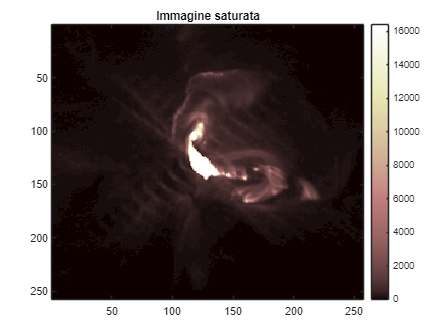

%Immagine saturata
imagesc(Imm);
colormap("pink"); colorbar;
title('Immagine saturata');

E si visualizza la PSF e le sue componenti:

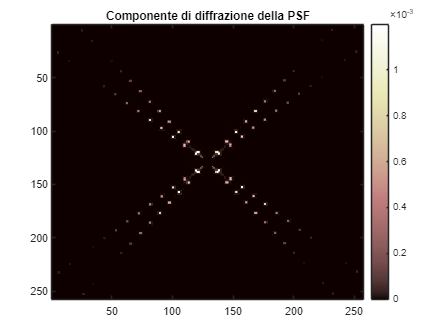

%Componente di diffrazione Kd
imagesc(Kd);
colormap("pink"); colorbar;
title('Componente di diffrazione della PSF')

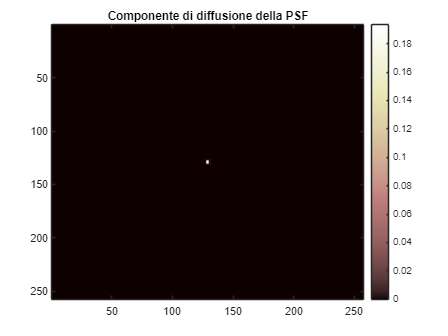

% %Visualizzazione 3D di Kd
% mesh(Kd)
% colormap pink; colorbar;
% title("Visualizzazione 3D di Kd"); 
% ylabel('colonne'); xlabel('righe');


%Componente di diffusione Kc
imagesc(Kc);
colormap("pink"); colorbar;
title('Componente di diffusione della PSF')

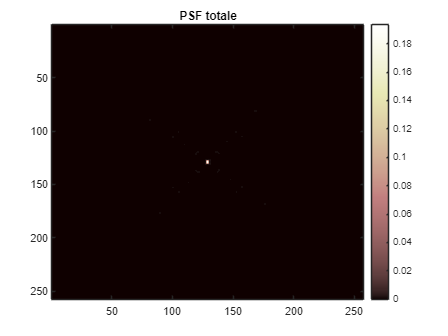

% %Visualizzazione 3D di Kc
% mesh(Kc)
% colormap pink; colorbar;
% title("Visualizzazione 3D di Kc")
% ylabel('colonne'); xlabel('righe');


%PSF totale
imagesc(K);
colormap("pink"); colorbar;
title('PSF totale');

%%per controllo generico, osservando la somma di Kd e Kc, si ottiene la stessa immagine:
% imagesc(Kd+Kc);
% colormap("pink"); colorbar;
% title('PSF totale come somma di Kd e Kc');

% %%Visualizzazione 3D di K
% mesh(K)
% colormap pink; colorbar;
% title("Visualizzazione 3D di K")
% ylabel('colonne'); xlabel('righe');

Per una migliore visualizzazione della PSF totale si applicano gli operatori puntuali "*Contrast Stretching*" e "*Trasformazione Logaritmica*".

L'immagine è in scala di rosa e, supponendo che i livelli di rosa siano L, siano $L_{min}=0$ il colore nero e $L_{max}=L-1$ il bianco. 

**Contrast Stretching:** si espande l’iniziale intervallo di contrasto della PSF (ottenuto determinando massimo $l_2$ e minimo $l_1$ valore dell'immagine) sulla gamma completa [0,L-1], dove L=256, attraverso la trasformazione: 

$K_{\textrm{view}} =\frac{K-l_1 }{l_2 -l_1 }\left(L-1\right)$;

**Trasformazione Logaritmica:** l’effetto è quello di espandere i pixel scuri di un' immagine e comprimere quelli chiari, attraverso la trasformazione:

$K_{\textrm{view}} =\frac{L-1}{\log \left(L\right)}\log \left(1+K\right)$.

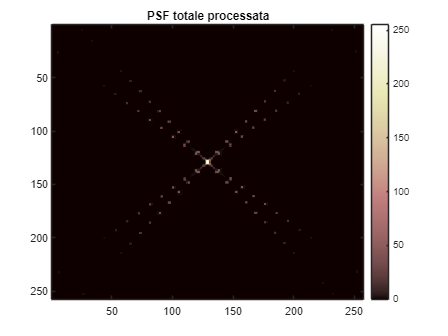

%Contrast Stretching 
l2=max(K,[], "all");
l1=min(K,[], "all");
K_view=(K-l1)/(l2-l1)*255;
%Trasformazione Logaritmica
K_view=log(K_view+1)*255/log(256);

%Visualizzazione
imagesc(K_view);
colormap("pink"); colorbar;
title('PSF totale processata')

clear l1; clear l2; clear K_view;

## Step II: Segmentazione

### Identificazione $S$

Si procede quindi con il primo punto dell'algoritmo DESAT, ovvero con l'identificazione della regione di saturazione. Per farlo bisogna identificare una soglia (in inglese threshold) che, se viene superata in un certo pixel, indica che quest'ultimo contiene un valore saturato. Sebbene la soglia per AIA sia di $16.383 \, DN/pixel$, come threshold si utilizza $15.000 \, DN/pixel$ per tener conto anche della zona di blooming. 

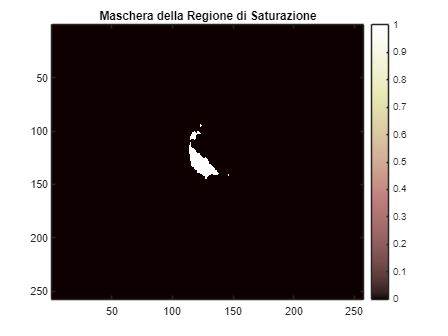

%costruzione della matrice logica Chi_S; se moltiplicata puntualmente con Imm,
%restituisce solo i valori dei pixel nella zona di saturazione e pone a
%zero quelli esterni (maschera).
Chi_S = (Imm>=15000);
imagesc(Chi_S);
colormap("pink"); colorbar;
title('Maschera della Regione di Saturazione')

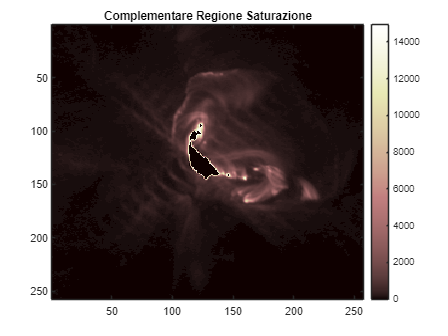

%VISUALIZZAZIONE ZONA COMPLEMENTARE A S

%Ricostruzione dell'immagine rimuovendo la zona saturata, tramite il prodotto
%puntuale di Imm e di 1-Chi_S (maschera precedente invertita)
imagesc((1-Chi_S).*Imm);
colormap("pink"); colorbar;
title('Complementare Regione Saturazione')

### Identificazione $F$

Si ricostruisce ora la zona delle frange associate ad $S$ nell'immagine. Per farlo, si considera $K_D * \textrm{X}_S$ e si azzerano i pixel nella zona di saturazione (grafico "*Frange associate alla Regione di Saturazione*"). Dopodiché, per cercare il supporto delle frange al di fuori di $S$, poiché  la matrice presenta tutti valori non nulli, si possono soltanto cercare i pixel il cui valore è al di sopra di una certa soglia $th=max(K_D) \times 10^{-3}$ (grafico "*Maschera delle Frange associate alla Regione di Saturazione*").

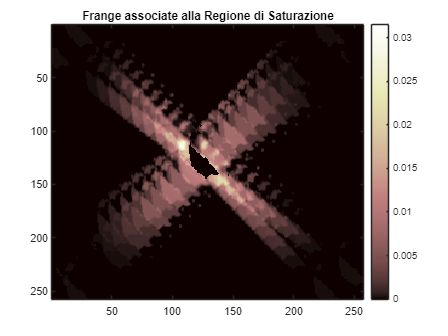

%Ricostruzione delle frange associate a S
F=conv2(Kd, Chi_S, "same").*(1-Chi_S);  %"same" => stessa taglia delle altre imgs, altrimenti sarebbe 513x513 
imagesc(F);
colormap("pink"); colorbar;
title('Frange associate alla Regione di Saturazione')

Si costruisce quindi la maschera *Chi_F* associata a $F$, tramite la ricerca dei valori che superano un certo threshold fuori dalla zona di saturazione:

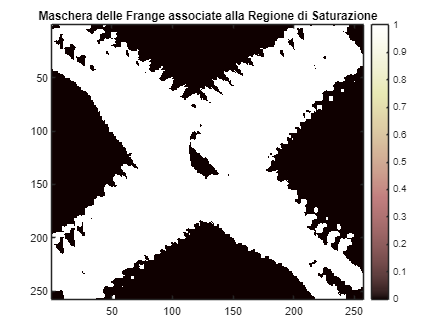

%Si fissa una soglia
th=max(Kd, [], "all")*1e-3;

%Costruzione della maschera associata alle frange analogamente a quanto
%fatto con Chi_S
Chi_F=F>=th;
imagesc(Chi_F);
colormap("pink"); colorbar;
title('Maschera delle Frange associate alla Regione di Saturazione')

### Costruzione $K_D^{S}$

Per identificare $S'$ e $BG$, bisogna eseguire la prima iterazione dell'algoritmo EM (punto 3 di DESAT). Bisogna quindi costruire $K_D^{S}: \mathbb{R}^{ | S|} \longrightarrow \mathbb{R}^{|F|}$, come una matrice di dimensione $|F| \times |S|$. Per farlo, innanzitutto si contorna $K_D$ con una cornice di $0$, in modo da poter sovrapporre l'immagine $Imm$ con un suo qualsiasi pixel in corrispondenza del centro di $K_D$ senza uscire da $K_D$. 

Si crea $K_D$ padded di dimensione $513 \times 513$.

%Zero-padding della PSF di diffrazione
Kdpad=padarray(Kd, [128 128], 0, "both"); 
%si mette cornice di 0 di dimensione 128 su tutti i lati, in tutte e due le dimensioni x e y, per arrivare a 513


%VISUALIZZAZIONE DI K_D PADDATA:
% imagesc(Kdpad);
% colormap("pink"); colorbar;
% title('Componente di diffrazione con padding')

Si costruisce quindi $K_D^{S}$: preso l'$n$-esimo pixel di $S$, sovrapporre $Kdpad$ sull'immagine facendo corrispondere ad $n$ il centro di $Kdpad$; a questo punto selezionare il valore di $Kdpad$ individuato dall' $m$-esimo pixel di $F$: è l'entrata $K_D^S(m,n)$. 

Si ragiona su questa costruzione con gli indici della matrice $256 \times 256$: preso un pixel $(i,j)$ in $S$, e un pixel $(h,k)$ in $F$, si ha che $K_D^S(m,n)= Kdpad(256-i+h, 256-j+k)$ dove $m,n$ sono gli indici rispettivamente del pixel  $(h,k)$ e del pixel  $(i,j)$ rispetto all'immagine srotolata e $(256, 256)$ è il centro di $Kdpad$. Si è quindi fatto un cambio di coordinate per cui il pixel $(k,h)$ di $F$ corrisponde al pixel $(256+(h-i), 256+(k-j))$ in $Kdpad$ e  ne segue un disegno esplicativo (in blu è rappresentata l'immagine coi suoi relativi indici, in nero $Kdpad$ e i suoi relativi indici corrispondenti):

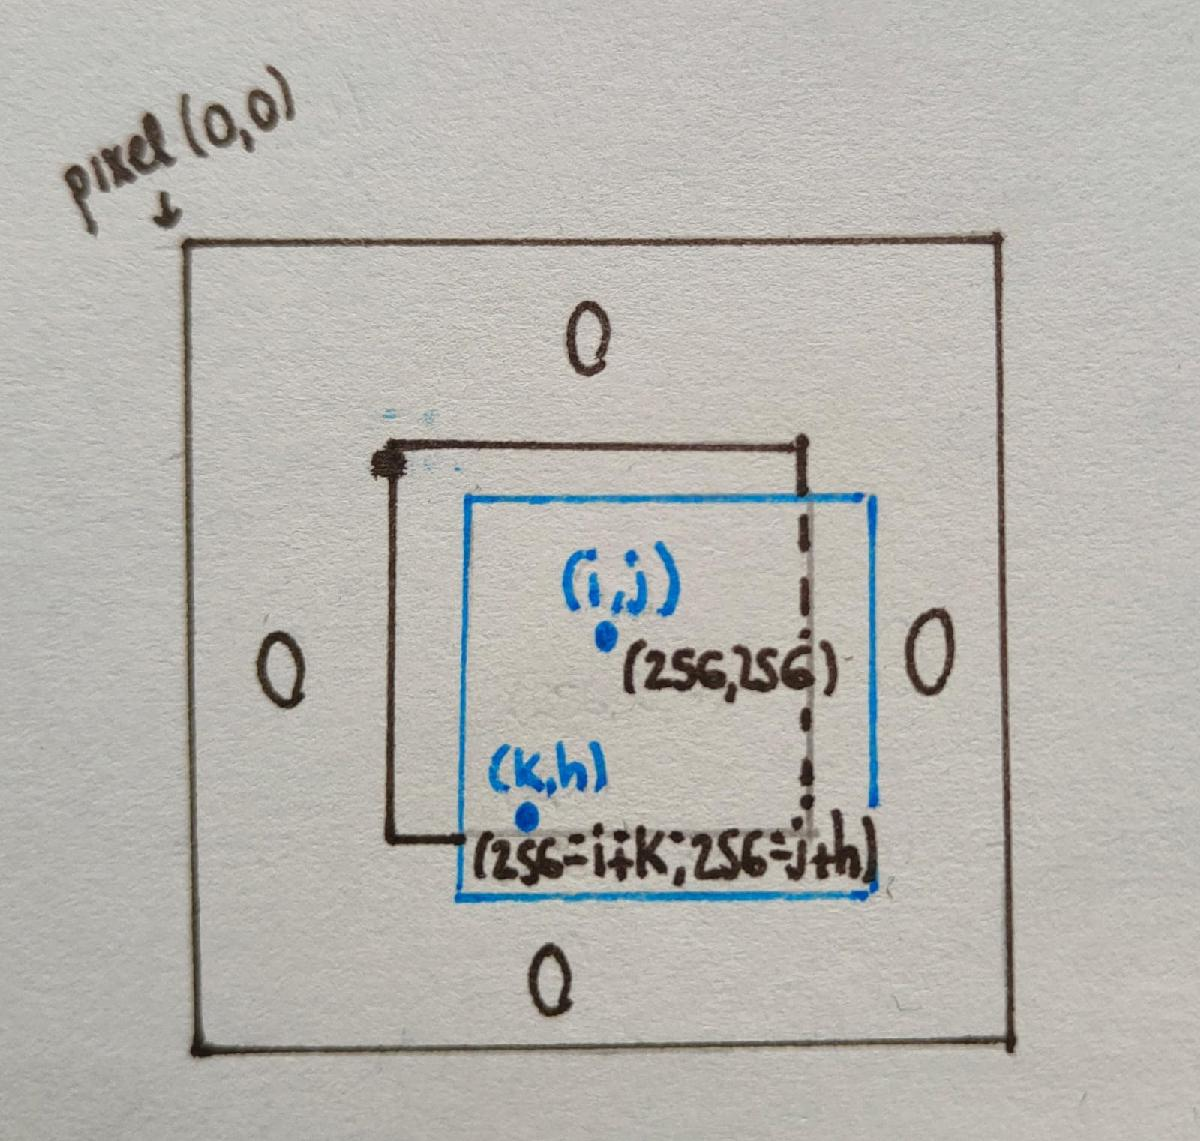

Sfruttando il fatto che MATLAB accetta gli indici "srotolati" per una matrice si consideri la seguente formulazione del problema:

Siano due vettori $v,w$ di taglia rispettivamente $n \times 1 \text{ e } m \times 1$, facendo$-v'+w$  si ottiene una matrice $m \times n$  le cui entrate sono le differenze componente per componente. Utilizzando la seguente formula per la costruzione di $K_D^S$ ma con gli indici srotolati 


$$(2) \qquad \qquad K_D^S(m,n)=K_{dpad}\left(\frac{513^2-1}{2}-n+m \right)$$
  

si giunge al seguente codice:

%Controllo del tempo di esecuzione per questo codice. Di seguito si riporta 
% questa formulazione essendo più veloce del codice con un ciclo for, che
% invece viene riportato come commento nella cella di comandi successiva


tic

%Cardinalità di S e di F
sizeS=nnz(Chi_S);
sizeF=nnz(Chi_F);


%indici per costruire KdS: IF, indici dei pixel nella frangia rispetto
%all'immagine srotolata, analogamente per IS. 
IF=find(Chi_F);
IS=find(Chi_S);


%costruzione della matrice degli indici: in ogni entrata (m,n) di IndiciKdS vi è
%l'indice V relativo al valore di Kdpadd (srotolata) che da 
% inserire in KdS(m,n) (=Kdpadd(V)).
IndiciKdS=(size(Kdpad,1).^2-1)/2-IS'+IF;


%Implementazione della formula (2). Si ha bisogno di un reshape
%perché avendo dato a Kdpad gli indici di Kdpad srotolata, MATLAB 
%restituisce KdS srotolata ma serve sizeF x sizeS.
KdS=reshape(Kdpad(IndiciKdS(:)), [sizeF, sizeS]);

toc 

Elapsed time is 0.098292 seconds.


clear IndiciKdS; 

Si visualizza la matrice circolante $K_D^S$:

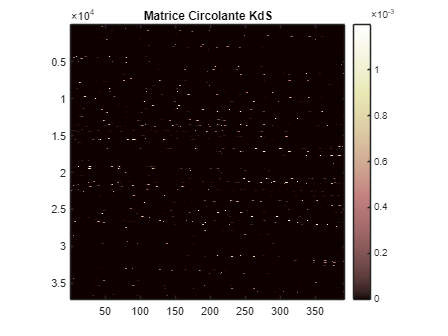

%visualizzazione della matrice circolante
imagesc(KdS); axis square;
colormap("pink"); colorbar;
title('Matrice Circolante KdS')

Per una maggior comprensione del codice qui sopra, si lascia qui di seguito commentato il codice che costruisce KdS con un ciclo for; i risultati sono gli stessi e il tempo di esecuzione è poco di più. 

% tic
% %Cardinalità di S e di F
% sizeS=nnz(Chi_S);
% sizeF=nnz(Chi_F);
% 
% 
% %Costruzione della matrice circolante KdS
% 
% KdS=zeros(sizeF, sizeS);
% [righeS, colS]=find(Chi_S);
% 
% IF=find(Chi_F);
% 
% for j=1:sizeS
%         Kcut = Kdpad((256-righeS(j)):(512-righeS(j)), (256-colS(j)):(512-colS(j)));
%         KdS(:,j)=Kcut(IF);
% end
% 
%toc
% 
% imagesc(KdS); axis square;
% colormap("pink"); colorbar;
% title('Matrice Circolante KdS')

### Identificazione $S'$ e $BG$

Una volta costruita la matrice circolante $K_D^S$ si può calcolare la correlazione utilizzando l'algoritmo Expectation Maximization (EM) riportato al punto 3 dell'algoritmo DESAT (esposto nella sezione "Background") per identificare la regione di saturazione primaria $S'$e e la regione di blooming $B$. 

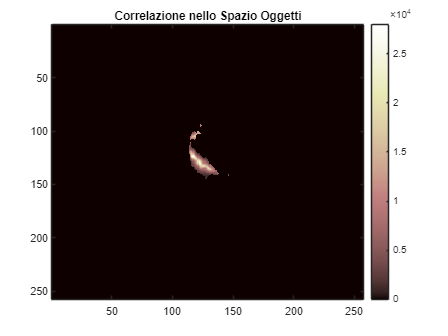

%Inizializzazione e Applicazione Algoritmo EM
C = EM(KdS, Imm(IF), BG(IF) , BG(IS), sizeF, sizeS, 1 );



%Calcolo della Correlazione di S con la Diffrazione nello Spazio Oggetti
C1 = zeros(size(Chi_S));
C1(IS) = C;

%visualizzazione della correlazione appena calcolata
imagesc(C1);
colormap("pink"); colorbar;
title('Correlazione nello Spazio Oggetti') 

Ci si riporta ora nello spazio immagine considerando $I_F=K_D^S \cdot C1$ e a cui si somma la componente di background ristretta alle frange $BG$.

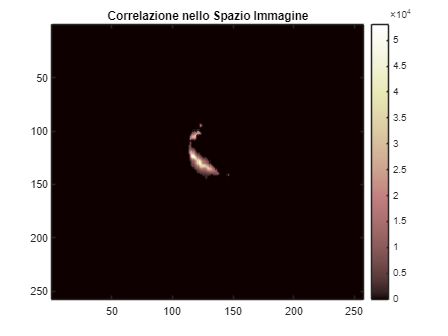

%Passaggio allo Spazio Immagini

%Definizione nello spazio immagine dove il primo termine indica il
%Background associato a S (ottenuto moltiplicando BG per la maschera di S)
%e il secondo termine è la convoluzione tra correlazione e componente di diffusione
C1_im=BG.*Chi_S+conv2(Kc, C1, "same");

%A causa della convoluzione si verificano "sfumature", ci si riporta nella zona
%di saturazione moltiplicando per la maschera di S
C1_imS=C1_im.*Chi_S;

imagesc(C1_im);
colormap("pink"); colorbar;
title('Correlazione nello Spazio Immagine')

clear C; clear C1;

Adesso si identifica la regione di Saturazione Primaria come la zona in cui la correlazione supera il valore di soglia 15000 DN/pixel (per l'ipotesi esposta nella sezione "Background" secondo cui gli effetti di diffrazione associati al blooming sono trascurabili) e la regione di Blooming come la zona in cui i valori non nulli non raggiungono tale valore. 

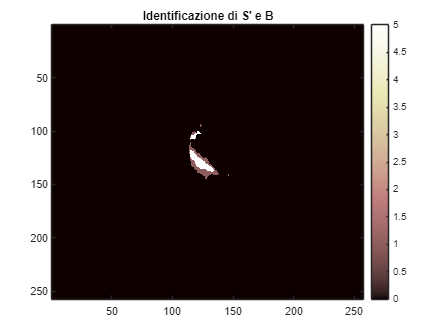

%Definizione delle maschere di regione di saturazione primaria e di blooming 

%maschera regione saturazione primaria
Chi_S1=(C1_imS>=15000);%saturazione primaria
%imagesc(Chi_S1);


%maschera regione di blooming
Chi_B=(C1_imS<15000 & C1_imS>0); %blooming
%imagesc(Chi_B);



%Visualizzazione e identificazione di S' e di B
%Per distinguere le due regioni, si assegnano valori differenti: alla
%regione di saturazione primaria viene assegnato valore 5 e alla regione di
%blooming valore 1

imagesc(5.*Chi_S1+1.*Chi_B); 
colormap("pink"); colorbar;
title("Identificazione di S' e B");

clear C1_im; clear C1_imS;


% %Visualizzazione 3D di S' e B
% mesh(2.*Chi_S1+1.*Chi_B)
% colormap pink; colorbar;
% ylabel('colonne');
% xlabel('righe');
% title("Visualizzazione 3D di S' e B")

Si costruisce la maschera della regione di saturazione primaria $S'$ per comodità d'implementazione.

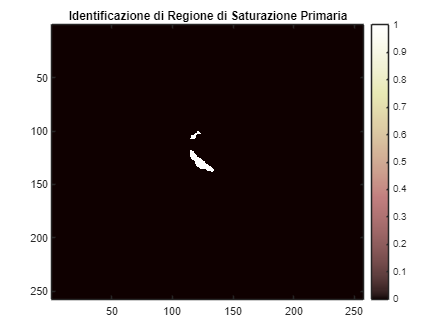

%Maschera di S'
imagesc(Chi_S1);
colormap("pink"); colorbar;
title("Identificazione di Regione di Saturazione Primaria")

## Identificazione di $F'$

Si identifica adesso la regione occupata dalle frange di diffrazione al di fuori della regione di saturazione prodotte dai pixel della regione di saturazione primaria:

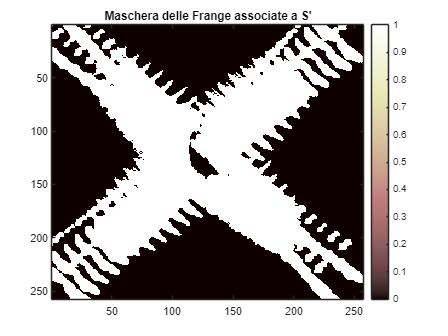

%Maschera di F'
%Soglia th fissata precedentemente
%Costruzione della maschera associata alle frange F'
Chi_F1=(conv2(Kd, Chi_S1, "same")>=th).*(1-Chi_S);

%Visualizzazione della maschera associata alle frange F'
imagesc(Chi_F1);
colormap("pink"); colorbar;
title("Maschera delle Frange associate a S'")

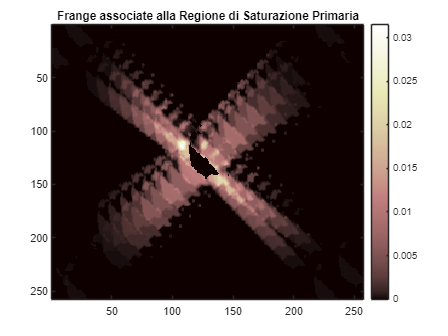

%Ricostruzione delle frange associate a S'
F1=Imm.*Chi_F1;
imagesc(F);
colormap("pink"); colorbar;
title('Frange associate alla Regione di Saturazione Primaria')

Analogamente a quanto svolto per la costruzione della matrice circolante $K_D^S$, si costruisce ora la matrice circolante $K_D^{S'}$:

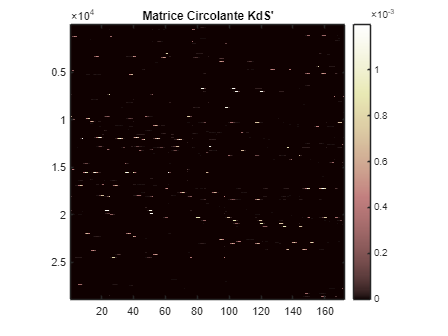

%Cardinalità di S1 e di F1
sizeS1=nnz(Chi_S1);
sizeF1=nnz(Chi_F1);


%indici per costruire KdS1: IF1, indici dei pixel nella frangia rispetto
%all'immagine srotolata, analogamente per IS1. 
IF1=find(Chi_F1);
IS1=find(Chi_S1);


%costruzione della matrice degli indici: in ogni entrata (m,n) di IndiciKdS1 vi è
%l'indice V relativo al valore di Kdpad (srotolata) che vanno 
% inseririti in KdS(m,n) (=Kdpad(V)).
IndiciKdS1=(size(Kdpad,1).^2-1)/2-IS1'+IF1;


%Si implementa la formula (2). Si ha bisogno di un reshape
%perché avendo dato a Kdpad gli indici di Kdpad srotolata, MATLAB
%restituisce KdS1 srotolata ma serve sizeF1 x sizeS1.
KdS1=reshape(Kdpad(IndiciKdS1(:)), [sizeF1, sizeS1]);

%Visualizzazione di KdS'
imagesc(KdS1); axis square;
colormap("pink"); colorbar;
title("Matrice Circolante KdS'")

clear IndiciKdS1; clear Kdpad; 

Per una maggior comprensione del codice qui sopra, si lascia commentato il codice che costruisce KdS' con un ciclo for; i risultati sono gli stessi e il tempo di esecuzione è di poco maggiore. 

% %Cardinalità di S' e di F'
% sizeS1=nnz(Chi_S1);
% sizeF1=nnz(Chi_F1);
% 
% %Costruzione della matrice circolante KdS'
% KdS1=zeros(sizeF1, sizeS1);
% [righeS1, colS1]=find(Chi_S1);
% 
% IF1=find(Chi_F1);
% for j=1:sizeS1
%         Kcut = Kdpad((256-righeS1(j)):(512-righeS1(j)), (256-colS1(j)):(512-colS1(j)));
%         KdS1(:,j)=Kcut(IF1);
% end

## Step III: Desaturazione

 Si esegue adesso il passo 6 dell'algoritmo DESAT descritto nella sezione "Background" per stimare il flusso nella zona di saturazione primaria S', utilizzando nuovamente EM: $x^{(k+1)}=x^{(k)} \cdot (K_D^{S'}) ^T \frac{I_{|F'}}{K_D^{S'} x^{(k)}+ BG_{|F'}$ dove $x^{(0)}=BG_{|S'}$ e, scelto il passo $k^*$  come iterazione ideale si considera $x^{(k^*)}$;

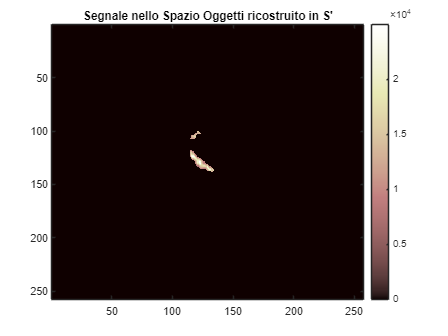

%Inizializzazione EM
IS1=find(Chi_S1);
IF1=find(Chi_F1);
%Applicazione EM con 3 iterazioni
X = EM(KdS1, Imm(IF1), BG(IF1) , BG(IS1), sizeF1, sizeS1, 3 );

%Identificazione regione saturazione
X2 = zeros(size(Chi_S1));
X2(IS1) = X;
imagesc(X2);
colormap("pink"); colorbar;
title("Segnale nello Spazio Oggetti ricostruito in S'")

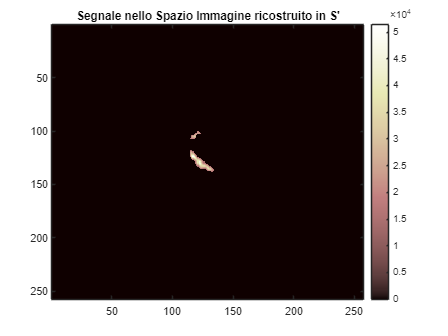

%Passaggio allo Spazio Immagini


%Definizione nello spazio immagine dove il primo termine indica il
%Background associato a S' (ottenuto moltiplicando BG per la maschera di S')
%e il secondo termine è la convoluzione tra il segnale ricostruito e la componente di diffusione
X1_im=BG.*Chi_S1+conv2(Kc, X2, "same");

%A causa della convoluzione si verificano "sfumature", ci si riporta nella zona
%di saturazione moltiplicando per la maschera di S'
X1_imS=X1_im.*Chi_S1;

imagesc(X1_imS);
colormap("pink"); colorbar;
title("Segnale nello Spazio Immagine ricostruito in S'");

clear X1_imS; clear X1_im;

## Step IV: Sintesi

Si combina adesso le immagini parziali, nelle varie regioni, per l’assemblaggio di un’unica immagine desaturata, come descritto al passo 7 dell'algoritmo DESAT riportato nella sezione "Background".

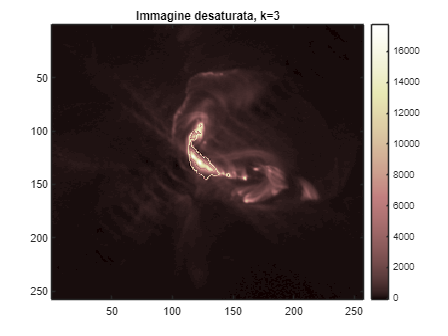

I_desat=Imm;

%Regione di Saturazione Primaria
KcX2=conv2(Kc,X2,"same");
I_desat(IS1)=KcX2(IS1);
clear KcX2;

%Regione di Blooming
IB=find(Chi_B);
I_desat(IB)=BG(IB);

%Regione delle Frange F'
I_desat(IF1)=Imm(IF1)-KdS1*X;

%Visualizzazione Immagine Desaturata
imagesc(I_desat);
colormap("pink"); colorbar;
title('Immagine desaturata, k=3');

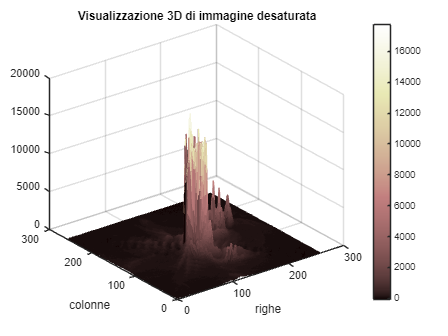

%Visualizzazione 3D dell'immagine desaturata
mesh(I_desat)
colormap pink; colorbar;
ylabel('colonne');
xlabel('righe');
title('Visualizzazione 3D di immagine desaturata')

Si può infine osservare l'immagine desaturata, in cui si è recuperata l'informazione relativa alla zona di saturazione. Si nota dal grafico 3D che effettivamente, rispetto all'immagine di partenza, i valori dell'immagine desaturata sono inferiori.  Aumentando il numero di iterazioni a $k=20$ e $k=100$, si osserva che nella zona di saturazione ci sono altre informazioni che potrebbero essere recuperate ma, all'aumentare dei passi, l'algoritmo di EM diventa più lento (la differenza tra $k=3$ e $k=20$ è ben più visibile della differenza tra $k=20$ e $k=100$). Si riportano le immagini ricostruite per una maggior comprensione:

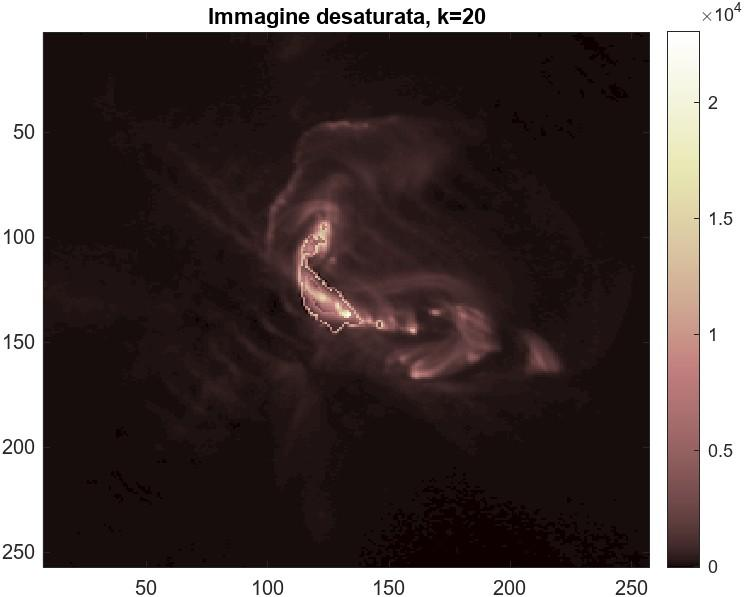   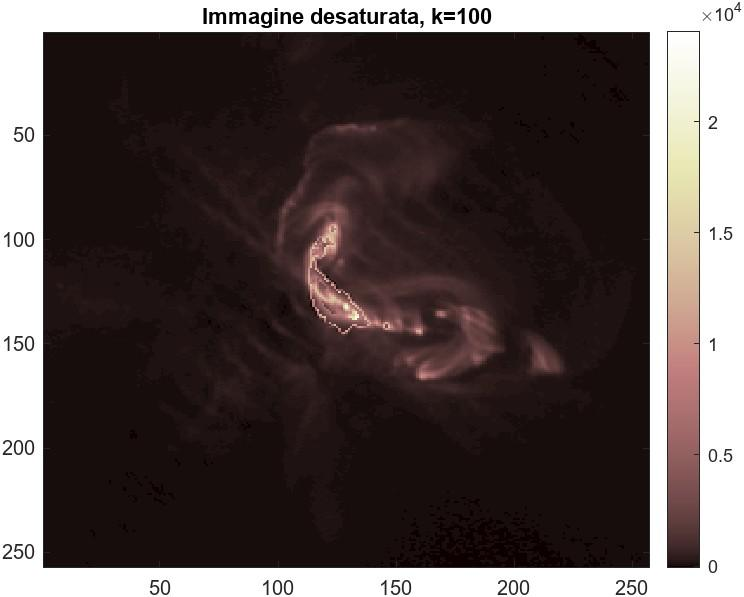

## Implementazione dell'algoritmo di Expectation Maximization

function [iterata] = EM(KdS, If, BGF, BGS, cardF, cardS, k)


%La funzione EM implementa l'algoritmo di Expectation Maximization x^(k+1)=x^k .* (KdS)' * (If ./ (KdS * x^k+ BGF)) 
%con x^0=BGS, e restituisce la k-esima iterazione. Gli input che necessita sono:

%KdS, matrice numerica di taglia cardF x cardS

%If, vettore di taglia cardF x 1

%BGF, vettore di taglia cardF x 1

%BGS, vettore di taglia cardS x 1

%cardF, uno scalare intero strettamente maggiore di 0

%cardS, uno scalare intero strettamente maggiore di 0

%k, il numero di iterazioni da eseguire



%controllo sull'input: dev'essere numerico
if(isnumeric(KdS) == 0 || isnumeric(If)==0 || isnumeric(BGF)==0 || isnumeric(BGS)==0 || isnumeric(cardF)==0 || isnumeric(cardS)==0 || isnumeric(k)==0)
    error("Uno degli input non e' numerico");
end



% controllo dimensionale sugli input

%KdS
if(size(KdS) ~= [cardF cardS])
    error("Dimensione della matrice Kds (primo input) errata");
end

%If
if(size(If) ~= cardF)
    error("Dimensione del vettore If (secondo input) errata");
end


%BGF
if(size(BGF) ~= cardF)
    error("Dimensione del vettore BGF (terzo input) errata");
end


%BGS
if(size(BGS) ~= cardS)
    error("Dimensione del vettore BGS (quarto input) errata");
end

%cardF e cardS
if(cardF<=0 || floor(cardF)~=ceil(cardF) || cardS<=0 || floor(cardS)~=ceil(cardS))
    error("Le cardinalità F e S (rispettivamente quinto e sesto input) devono essere un intero strettamente maggiore di zero");
end

if(~isscalar(cardS))
    error("La cardinalità di S (sesto input) deve essere scalare");
end

if(~isscalar(cardF))
    error("La cardinalità di F (quinto input) deve essere scalare");
end


% controllo sulla sensatezza del numero di iterazioni richieste
%k
if(k<0 || floor(k)~=ceil(k))
    error("Il numero delle iterazioni (settimo input) deve essere un intero maggiore di zero");
end


%controllati gli input, procede con l'implementazione di EM:

    iterata =  BGS;
    %inizializzazione
    uni = ones(cardF,1);

    %algoritmo iterativo
    for i=1:k
        iterata= iterata.*(KdS' * ((If./(KdS*iterata+ BGF))))./(KdS'* uni);
    end

end